load part4_1.dat
X = part4_1

X =          0         0    0.0020
    0.0100         0         0
    0.0200         0         0
    0.0300         0         0
    0.0400         0         0
    0.0500         0         0
    0.0600         0         0
    0.0700         0         0
    0.0800         0    0.0020
    0.0900         0         0


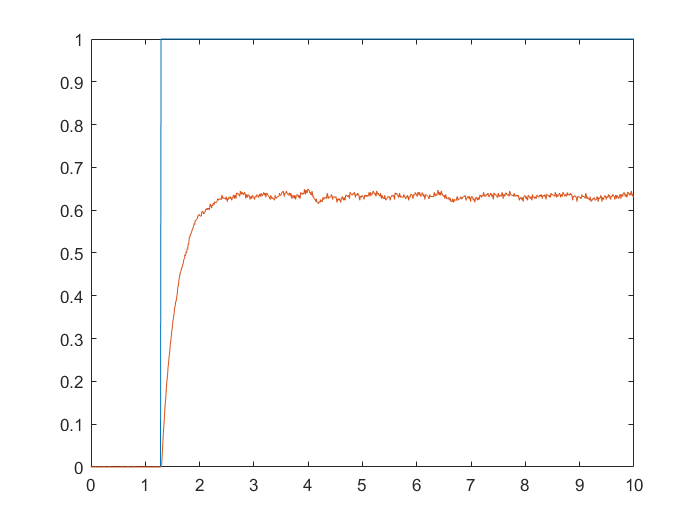

plot(X(:,1),X(:,2)) % Gives a plot of the input vs. sample number 
hold on
plot(X(:,1),X(:,3)) % Gives a plot of the output vs. sample number 
hold off

% Trim data and subtract min
Start = 101;
Final = 270;

Y = X(Start:Final,:);

minVal = min(Y(:,3));

for i = Start:Final
    Y(i - Start + 1,3)=X(i,3) - minVal;
end

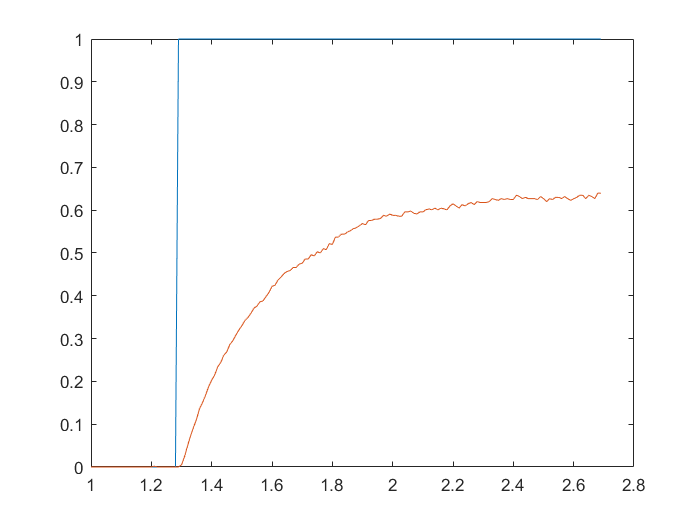

% Plot cropped data

plot(Y(:,1),Y(:,2)) % Gives a plot of the input vs. sample number 
hold on
plot(Y(:,1),Y(:,3)) % Gives a plot of the output vs. sample number 
hold off

% Remove HF noise using low-pass filter
% By observation, the period of the response is about 200 samples long.
% Choose w >> 2 pi/200.
w = 0.2;
N = 5;

W = idfilt(Y(:,3), N, w, 'noncausal');

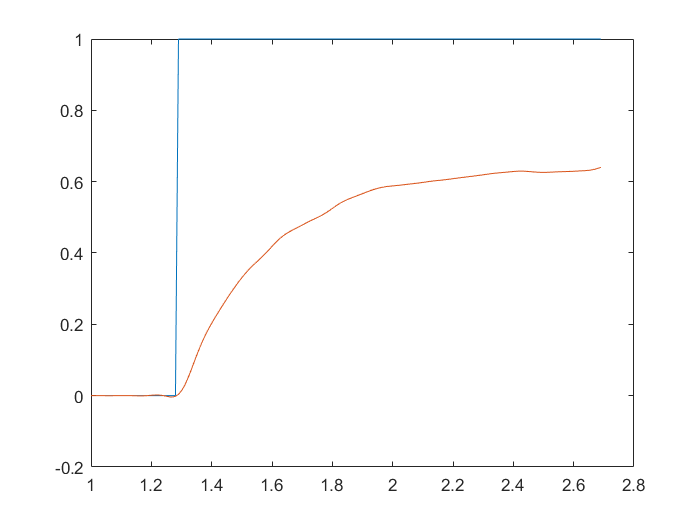

plot(Y(:,1),Y(:,2))
hold on;
plot(Y(:,1), W) % Gives a plot of the input vs. sample number 